# Magnetometer Callibration

## Import data

clc; clear; close all;

rotation = load("trainingData/calib1_rotate.mat");
GT_rotation = squeeze(rotation.out.GT_rotation.signals.values);
GT_time = squeeze(rotation.out.GT_rotation.time);
time = squeeze(rotation.out.GT_time.signals.values);
Mraw = squeeze(rotation.out.Sensor_MAG.signals.values)';
M_time = squeeze(rotation.out.Sensor_MAG.time)';

Mx   = Mraw(:,2);
My   = Mraw(:,3);

% Combine for 2D
XY_raw = [Mx, My];

## Calibration function

function calParams = calibrateMagnetometer2D_nonlinear(rawData, rawGTData)
    
    %% Normalize the Raw data
    % Ensures numerical stability in optimization
    mu = mean(rawData);
    sigma = std(rawData);
    normData = (rawData - mu) ./ sigma;

    x = normData(:,1);
    y = normData(:,2);

    %% Nonlinear ellipse fitting with robust loss
    % Parameters: [cx, cy, a, b, theta]
    x0 = [mean(x), mean(y), std(x), std(y), 0];  % initial guess

    % Residuals for optimization
    ellipseResiduals = @(p) (( ...
        ((x - p(1))*cos(p(5)) + (y - p(2))*sin(p(5))).^2 / p(3)^2 + ...
        ((x - p(1))*sin(p(5)) - (y - p(2))*cos(p(5))).^2 / p(4)^2 - 1 ...
    ));

    % Cost: log(1 + residual^2)
    Cost = @(p) sum(log(1 + ellipseResiduals(p).^2));

    options = optimoptions('fminunc','Display','off','Algorithm','quasi-newton');
    p_fit = fminunc(Cost, x0, options);

    %% Outlier rejection
    res = ellipseResiduals(p_fit);
    threshold = 0.1;  % Ensure that most data is used for training
    inliers = abs(res) < threshold;

    x_in = x(inliers);
    y_in = y(inliers);

    %% Re-fit with inliers only (least-squares)
    ellipseResiduals_in = @(p) (( ...
        ((x_in - p(1))*cos(p(5)) + (y_in - p(2))*sin(p(5))).^2 / p(3)^2 + ...
        ((x_in - p(1))*sin(p(5)) - (y_in - p(2))*cos(p(5))).^2 / p(4)^2 - 1 ...
    ));

    p_fit = fminunc(@(p) sum(ellipseResiduals_in(p).^2), p_fit, options);

    %% Calibration (translate, rotate, scale)
    cx = p_fit(1); 
    cy = p_fit(2);
    offset_norm = [cx, cy];

    a = p_fit(3); 
    b = p_fit(4);

    theta = p_fit(5);

    % Hard iron correction (translation)
    x_shift = x - cx;
    y_shift = y - cy;

    % Rotation matrix
    R = [cos(theta), -sin(theta); sin(theta), cos(theta)];
    rotated = R' * [x_shift'; y_shift'];

    % Soft iron correction (scaling)
    avg_scale = mean([1/a, 1/b]);
    scaleMatrix = diag([avg_scale, avg_scale]);
    calibrated_norm = scaleMatrix * rotated;

    % Denormalize: reverse scaling and offset
    calibratedData = (calibrated_norm' .* sigma) + mu;
    calibratedData = calibratedData - mean(calibratedData);

    %% Final offset and scale matrix in rawData space
    offset = mu + offset_norm .* sigma;
    scaleMatrix = scaleMatrix * R';

    %% Alignment
    % Yaw for GT
    yaw_gt = quat2eul(rawGTData, 'ZXY');  % [yaw, pitch, roll]
    yaw_gt = yaw_gt(:,1);                   % Take yaw only (in radians)
    yaw_gt = unwrap(yaw_gt);    % Unwrap to prevent jumps at ±π
    
    % Yaw for Mag
    yaw_mag = atan2(calibratedData(:,2), calibratedData(:,1));
    yaw_mag = unwrap(yaw_mag);
    
    % Represent both as 2D heading vectors
    v_gt = [cos(yaw_gt), sin(yaw_gt)];
    v_mag = [cos(yaw_mag), sin(yaw_mag)];
    
    % Center vectors
    v_gt_centered = v_gt - mean(v_gt, 1);
    v_mag_centered = v_mag - mean(v_mag, 1);
    
    % Compute 2x2 covariance matrix
    C = v_mag_centered' * v_gt_centered;
    
    % SVD on 2x2 matrix
    [U, ~, V] = svd(C);
    
    % Optimal rotation matrix (ensures proper rotation)
    R_opt = V * U';
    
    % Store all as a struct
    calParams.mu          = mu;
    calParams.sigma       = sigma;
    calParams.offset_norm = offset_norm;
    calParams.scaleMatrix = scaleMatrix;
    calParams.R_opt          = R_opt;

    %% Debugging 
    % Output diagnostics
    % figure;
    % plot(calibratedData(:,1), calibratedData(:,2), '.');
    % title('Calibrated Data (Robust Fit)'); 
    % axis equal;
    % diagnostics.inlier_ratio = mean(inliers);
    % disp(diagnostics.inlier_ratio)
    % r = sqrt(sum(calibratedData.^2, 2));
    % fprintf("Percentage of inliers: %.4f, Mean radius: %.4f, Std deviation: %.4f\n", diagnostics.inlier_ratio, mean(r), std(r));

end

## Save the calibration parameters

calParams = calibrateMagnetometer2D_nonlinear(XY_raw, GT_rotation);
save("MAG_calParams.mat", "calParams");

## Applying the calibration params

function [calibratedNew, yaw_mag]= applyMagnetometerCalibration2D(XY_new, calParams)
    % Unpack the struct
    mu          = calParams.mu;
    sigma       = calParams.sigma;
    offset_norm = calParams.offset_norm;
    scaleMatrix = calParams.scaleMatrix;
    R_opt       = calParams.R_opt;

    % Normalize
    % Important to do so because the transformations were done in the
    % normalized space of the clibration data.
    XY_norm = (XY_new - mu) ./ sigma;
    % Hard iron correction
    XY_centered = XY_norm - offset_norm;
    % Scale
    calibrated_norm = (scaleMatrix * XY_centered')';
    % Heading alignment rotation (align to GT yaw frame)
    calibrated_rot = (R_opt * calibrated_norm')';
    % Denormalize
    calibratedNew = (calibrated_rot .* sigma) + mu;
    % Recenter (Not sure if necessary)
    calibratedNew = calibratedNew - mean(calibratedNew);
    
    %% Convert to yaw
    % Yaw for Mag
    yaw_mag = atan2(calibratedNew(:,2), calibratedNew(:,1));
    yaw_mag = unwrap(yaw_mag);

end

calParams = load("MAG_calParams.mat")

calParams = struct with fields:
    calParams: [1×1 struct]


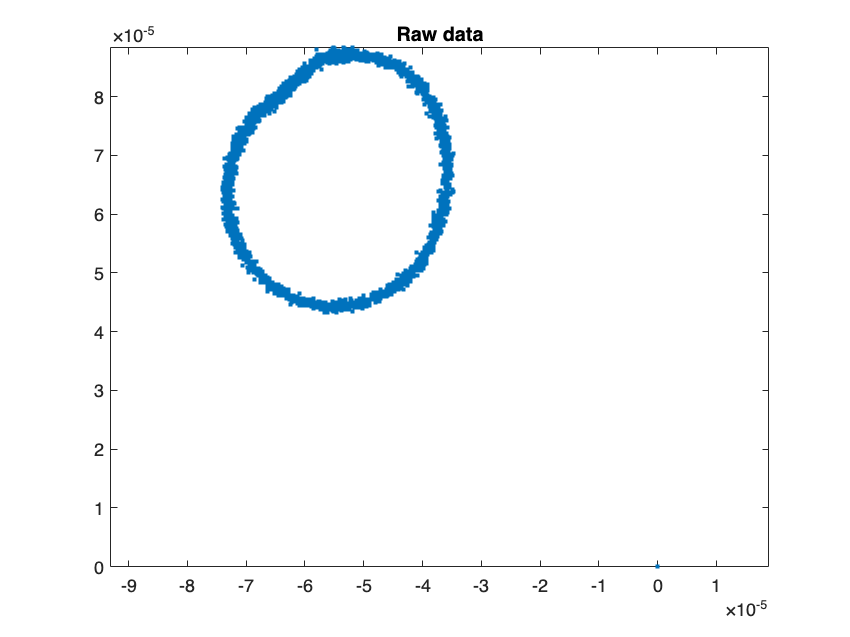

[calMag, yaw_mag]= applyMagnetometerCalibration2D(XY_raw, calParams.calParams);

figure;
plot(XY_raw(:,1), XY_raw(:,2), '.');
title('Raw data'); 
axis equal;

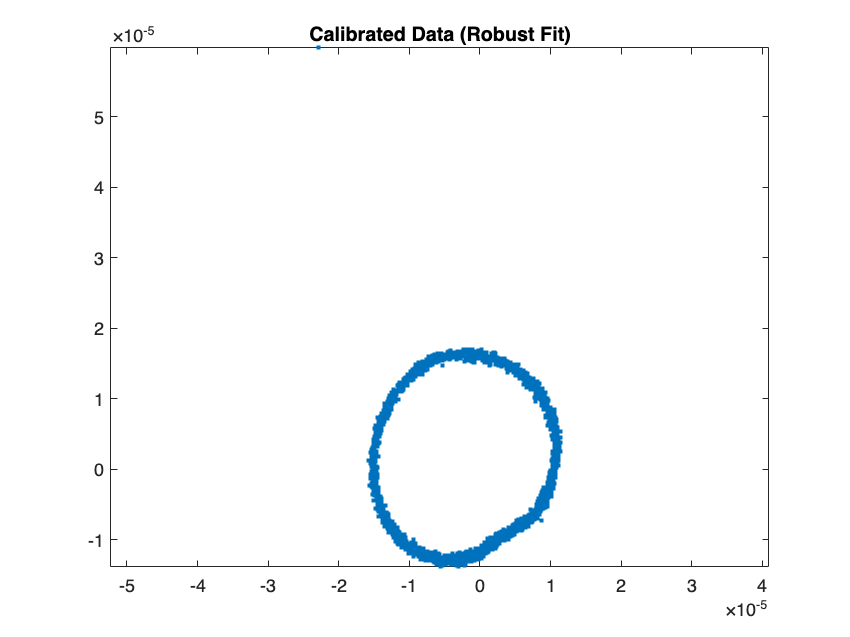


figure;
plot(calMag(:,1), calMag(:,2), '.');
title('Calibrated Data (Robust Fit)'); 
axis equal;

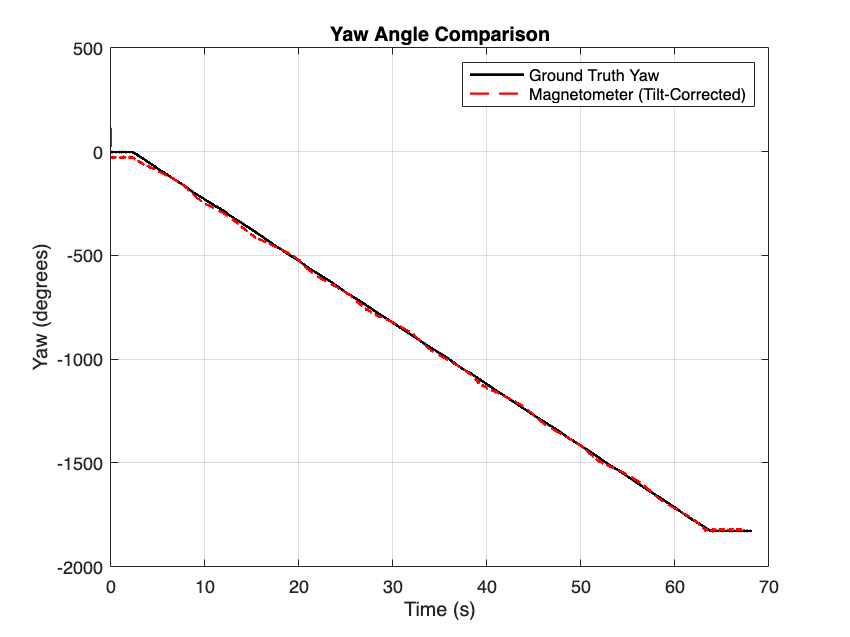



yaw_gt = quat2eul(GT_rotation, 'ZXY');  % [yaw, pitch, roll]
yaw_gt = yaw_gt(:,1);                   % Take yaw only (in radians)
yaw_gt = unwrap(yaw_gt);    % Unwrap to prevent jumps at ±π

v_gt = [cos(yaw_gt), sin(yaw_gt)];
v_gt_centered = v_gt - mean(v_gt, 1);

figure;
plot(time, rad2deg(yaw_gt), 'k', 'LineWidth', 1.5); hold on;
plot(M_time, rad2deg(yaw_mag), 'r--', 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Yaw (degrees)');
legend('Ground Truth Yaw', 'Magnetometer (Tilt-Corrected)');
title('Yaw Angle Comparison');
grid on;


yaw_error = wrapToPi(yaw_mag - yaw_gt);
yaw_rmse = sqrt(mean(yaw_error.^2));
fprintf("RMSE after frame alignment: %.2f°\n", rad2deg(yaw_rmse));

RMSE after frame alignment: 12.38°


## Alignment, Comparison and RMSE calculations

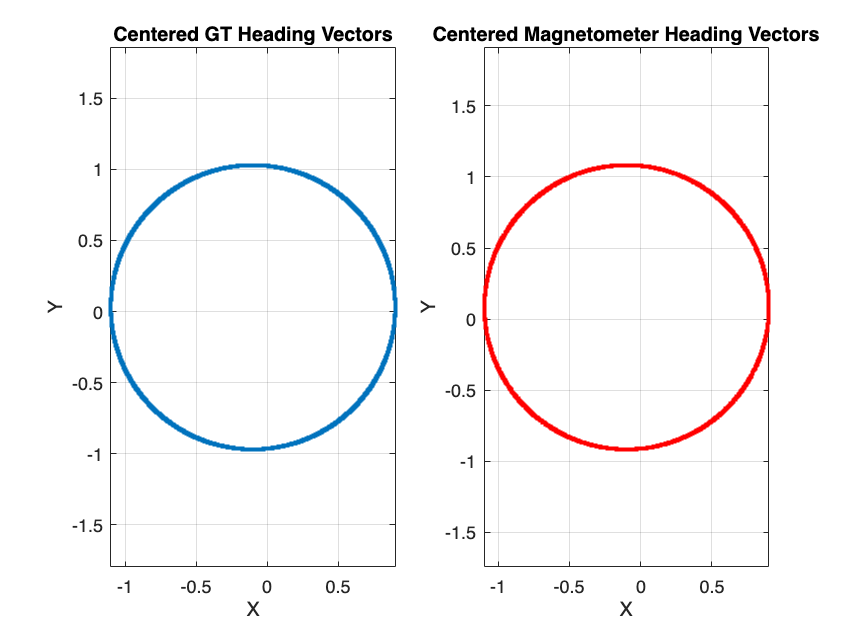

% Yaw for GT
yaw_gt = quat2eul(GT_rotation, 'ZXY');  % [yaw, pitch, roll]
yaw_gt = yaw_gt(:,1);                   % Take yaw only (in radians)
yaw_gt = unwrap(yaw_gt);    % Unwrap to prevent jumps at ±π

% Yaw for Mag
yaw_mag = atan2(calMag(:,2), calMag(:,1));
yaw_mag = unwrap(yaw_mag);

% Represent both as 2D heading vectors
v_gt = [cos(yaw_gt), sin(yaw_gt)];
v_mag = [cos(yaw_mag), sin(yaw_mag)];

% Center vectors
v_gt_centered = v_gt - mean(v_gt, 1);
v_mag_centered = v_mag - mean(v_mag, 1);

figure;
subplot(1,2,1);
plot(v_gt_centered(:,1), v_gt_centered(:,2), '.', 'DisplayName', 'GT');
axis equal; grid on;
xlabel('X'); ylabel('Y');
title('Centered GT Heading Vectors');

subplot(1,2,2);
plot(v_mag_centered(:,1), v_mag_centered(:,2), 'r.', 'DisplayName', 'Mag');
axis equal; grid on;
xlabel('X'); ylabel('Y');
title('Centered Magnetometer Heading Vectors');